# Testing the (Cramer 2-beam) Purturbation Method

## Clear variables between Runs:

clear % clear variables and everything
clc % clear command window

## Set up Save Path

%saveDir = 'D:\Research\Dr. Onofreis projects\DS MATLAB CODE\Github_Shared_Code\Relay-Phased-Array-Optimization-main\Saved_Results';
%if ~exist(saveDir, 'dir')
%    mkdir(saveDir);
%end

## Select Parameters:

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
params.freq = 3e9;
params.lambda = 3e8 / params.freq; 
lambda = params.lambda; 
k0     = 2*pi / lambda;
%params.N = 9;
%N = params.N; %Number of drones
fast_peaks = true;          % Crammer peak-finder selector

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate

## Generate Initial Configuration (To serve as a starting point for our optimization)

% Initialize nieve 9-element "double cross" coordinates
%x = [0 0 0 0.5*lambda -0.5*lambda 0.5*lambda -0.5*lambda lambda -lambda]';
%y = [0 0.5*lambda -0.5*lambda 0 0 0.5*lambda -0.5*lambda lambda -lambda]';
    
% Initialize Daniil's "good" version of the 9-element "double cross" coordinates
%z = zeros(1,N);
%d1 = 0.422 * lambda;
%d2 = 0.554 * lambda;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize Eric's 'better' version (specifically for 120 degrees)
%d1 = 0.049553426571036;
%d2 = 0.049015017974167;
%[x,y] = d1d2Convert(d1,d2,N);

% Initialize test version with two elements
%x = [0 lambda/2];
%y = [0 0];

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];


% Initialize Eric's "true correct and optimal 9 element ones" from the meeting with everybody
% (double cross with two radii)
%x = [0	-0.042211347450806	0.042211347450806	0	0	0.039173549691350	-0.039173549691350	-0.039173549691350	0.039173549691350];
%y = [0	0	0	0.042211347450806	-0.042211347450806	0.039173549691350	0.039173549691350	-0.039173549691350	-0.039173549691350];

% Initialize Eric's 13 element coordinates
%x = [0 0.0150 0.0075 -0.0075 -0.0150 -0.0075 0.0075 0.0866 0.0000 -0.0866 -0.0866 -0.0000 0.0866];
%y = [0 0 0.0130 0.0130 0.0000 -0.0130 -0.0130 0.0500 0.1000 0.0500 -0.0500 -0.1000 -0.0500];

% Initialize test version without center emitter
%x(1) = [];
%y(1) = [];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Compare 5, 9(ring), 13 element cases

% Eric's optimal "5 element setup"
%x = [0, 0.019598444542977, 0, -0.019598444542977, 0];
%y = [0, 0, 0.019598444542977, 0, -0.019598444542977];

% Initialize "All on one ring" version of the 9-element "double cross" coordinates
% This is equivalent to an regular octogon with radius 0.05 starting at (0.05,0).
%z = zeros(1,N);
% for 5 elements
%d1 = 0.019598444542977;
%d2 = 0.019598444542977;
% for 9 elements
%d1 = 0.5 * lambda;
%d2 = 0.5 * lambda;
d1 = 0.04880;
d2 = 0.04880;
[x,y] = d1d2Convert(d1,d2,9) %Change to 5,9,13 apropriatly

x =          0    0.0488    0.0000   -0.0488   -0.0000    0.0345   -0.0345   -0.0345    0.0345


y =          0         0    0.0488    0.0000   -0.0488    0.0345    0.0345   -0.0345   -0.0345



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Eric's special calculated emitter positions (2/25/26)

% N=5
%x = [0	0.019598452160414	0.000000000000000	-0.019598452160414	-0.000000000000000];
%y = [0	0	0.019598452160414	0.000000000000000	-0.019598452160414];

%N=9
%x = [0	0.0505	0.0357	0.0000	-0.0357	-0.0505	-0.0357	-0.0000	0.0357];
%y = [0	0	0.035713085910583	0.050505930448942	0.035713085910583	0.000000000000000	-0.035713085910583	-0.050505930448942	-0.035713085910583];

%N=13
%x = [0	0.050600639149324	0.043821438951044	0.025300319574662	0.000000000000000	-0.025300319574662	-0.043821438951044	-0.050600639149324	-0.043821438951044	-0.025300319574662	-0.000000000000000	0.025300319574662	0.043821438951044];
%y = [0	0	0.025300319574662	0.043821438951044	0.050600639149324	0.043821438951044	0.025300319574662	0.000000000000000	-0.025300319574662	-0.043821438951044	-0.050600639149324	-0.043821438951044	-0.025300319574662];

%N=17
%x = [0	0.050600865112511	0.046749103604814	0.035780214854963	0.019364112741899	0.000000000000000	-0.019364112741899	-0.035780214854963	-0.046749103604814	-0.050600865112511	-0.046749103604814	-0.035780214854963	-0.019364112741899	-0.000000000000000	0.019364112741899	0.035780214854963	0.046749103604814];
%y = [0	0	0.019364112741899	0.035780214854963	0.046749103604814	0.050600865112511	0.046749103604814	0.035780214854963	0.019364112741899	0.000000000000000	-0.019364112741899	-0.035780214854963	-0.046749103604814	-0.050600865112511	-0.046749103604814	-0.035780214854963	-0.019364112741899];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test multiples of geometric pattern
%x = (1.1)*x;
%y = (1.1)*y;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test Single emitter for 9 elements
%A_single = [1, 1, 0, 0, 0, 0, 0, 0, 0];
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Test Linear emitter for 9 elements
%x = linspace(-4,4,9).*(0.5*lambda);
%y = zeros(1,9);

## Plot: 2-Beam Function (Cramer Version)

phi_0_1 = deg2rad(225);
phi_0_2 = deg2rad(225+120);
phi_0_set = [phi_0_1 phi_0_2];
Max_iter = 200;
eps_dB = -20;
null_phi_list_1 = phi_0_2;
null_phi_list_2 = phi_0_1;
N = numel(x);
save_plots = false;
cone_rad   = deg2rad(0);   % Crammer constraint cone radius

%{
results_2A = perturb_method_v23(Max_iter, eps_dB, x, y, ...
    phi_0_1, ...
    'show_plots', false, ...
    'verbose', false, ...
    'null_phi', null_phi_list_1, ...
    'show_final_plot',  true, ...
    'const_null_update', false)
results_2B = perturb_method_v23(Max_iter, eps_dB, x, y, ...
    phi_0_2, ...
    'show_plots', false, ...
    'verbose', false, ...
    'null_phi', null_phi_list_2, ...
    'show_final_plot',  true, ...
    'const_null_update', false)
%}

results_2A = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, ...
    phi_0_1, ...
    'null_phi',        null_phi_list_1, ...
    'cone_rad',        cone_rad, ...
    'show_plots',      false, ...
    'show_final_plot', false, ...
    'verbose',         false, ...
    'return_funcs',    false)

results_2A = struct with fields:
                                  method: 'Crammer_Simultaneous_Constraints'
                              fast_peaks: 1
                         final_iteration: 4
                             final_epoch: 4
                              total_time: 0.1534
                        elapsed_cpu_time: 0.0800
                             focus_angle: 3.9270
                         focus_angle_deg: 225
                              null_angle: 6.0214
                          null_angle_deg: 345
                                cone_rad: 0
                          final_function: [-0.4040 + 0.0000i -0.4125 + 0.0000i -0.4207 + 0.0000i -0.4288 + 0.0000i -0.4366 + 0.0000i -0.4442 + 0.0000i -0.4515 + 0.0000i -0.4586 + 0.0000i -0.4655 + 0.0000i -0.4721 + 0.0000i … ] (1×1000 double)
                              F_at_phi_0: 6.7919
                               F_at_null: 2.0059e-16
                                   A_eff: [9×1 double]
                          

Final plot 1:

test_F_total_A = F2d_v2(phi_mesh, results_2A.A_eff, x, y, [], k0);

Unrecognized function or variable 'F2d_v2'.

%bw1 = directivity_met_v2(phi_mesh, test_F_total, phi_0_1);
%bw2 = directivity_met_v2(phi_mesh, test_F_total, phi_0_2);
lab_1 = "Final Plot: Analitic Method by Simultaneous Constraints";
%lab_1 = "Final Plot: Mosier 2-Beam";
            % View function graph
% Withot BW Edges
plot_pattern_v4(phi_mesh, ...
    abs(test_F_total_A), ...
    'label',lab_1, ...
    'phi_0', phi_0_1, ...
    'show_plots', true, ...
    'cone_rad', [], ...
    'null_phi', null_phi_list_1,...
    'iter', results_2A.final_iteration);



results_2B = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, ...
    phi_0_2, ...
    'null_phi',        null_phi_list_2, ...
    'cone_rad',        cone_rad, ...
    'show_plots',      false, ...
    'show_final_plot', true, ...
    'verbose',         false, ...
    'return_funcs',    false)

test_F_total_B = F2d_v2(phi_mesh, results_2B.A_eff, x, y, [], k0);
%bw1 = directivity_met_v2(phi_mesh, test_F_total, phi_0_1);
%bw2 = directivity_met_v2(phi_mesh, test_F_total, phi_0_2);
lab_1 = "Final Plot: Analitic Method by Simultaneous Constraints";
%lab_1 = "Final Plot: Mosier 2-Beam";
            % View function graph
% Withot BW Edges
plot_pattern_v4(phi_mesh, ...
    abs(test_F_total_B), ...
    'label',lab_1, ...
    'phi_0', phi_0_2, ...
    'null_phi', null_phi_list_2,...
    'show_plots', true, ...
    'cone_rad', [], ...
    'iter', results_2B.final_iteration);
    freq   = 3e9;
    lambda = 3e8 / freq;
    k0     = 2*pi / lambda;
F_reconstructed = F2d_v2(phi_mesh, results_2A.A_eff, x, y, [], k0);

max(abs(F_reconstructed - results_2A.final_function))
A_total = results_2A.A_eff + results_2B.A_eff;

test_F_total = F2d_v2(phi_mesh, A_total, x, y, [], k0);

test_F_totalA = results_2A.final_function + results_2B.final_function;

max(abs(test_F_total - test_F_totalA))

% Add the two plots together to get 2-beam plot


% Add raw plots
%test_F_total = results_2A.final_function + results_2B.final_function;
test_F_totalA = (N*results_2A.final_function/max(abs(results_2A.final_function))) ...
+ (N*results_2B.final_function/max(abs(results_2B.final_function)));

% Add scaled coefficients
A_total = (N*results_2A.A_eff ./ max(abs(results_2A.final_function))) ...
+ (N*results_2B.A_eff ./ max(abs(results_2B.final_function)));

% Use F2D function to generate new effective plot
freq   = 3e9;
lambda = 3e8 / freq;
k0     = 2*pi / lambda;
mesh_len = 1000; % length of phi-mesh for plotting pattern
phi_mesh = linspace(0, 2*pi, mesh_len+1);
phi_mesh(end) = [];   % remove 2pi duplicate

%test_F_total = F2d_v2(phi_mesh, A_total, x, y, [], k0);
%test_F_total = F2d_v2(phi_mesh, A_total, x, y, [], k0) ...
%.* max(abs(test_F_totalA)) ./ max(abs(F2d_v2(phi_mesh, A_total, x, y, [], k0)));

% Current-combination version
F_tmp = F2d_v2(phi_mesh, A_total, x, y, [], k0);
den = max(abs(F_tmp));
if den < 1e-12
    warning('F_tmp nearly zero — skipping normalization');
    test_F_total = F_tmp;
else
    test_F_total = F_tmp * (max(abs(test_F_totalA)) / den);
end

% Compare Plot-combination vs. Current-combination versions
max(abs(test_F_totalA - test_F_total))

%bw1 = directivity_met_v2(phi_mesh, test_F_total, phi_0_1);
%bw2 = directivity_met_v2(phi_mesh, test_F_total, phi_0_2);
%lab_1 = "Final Plot: Basic (Superposition) 2-Beam";
lab_1 = "Final Plot: Simultaneous Constraints (Superposition) 2-Beam";
%lab_1 = "Final Plot: Mosier 2-Beam";
            % View function graph
% Withot BW Edges
plot_pattern_v4(phi_mesh, ...
    abs(test_F_total), ...
    'label',lab_1, ...
    'phi_0', phi_0_set, ...
    'show_plots', true, ...
    'cone_rad', [], ...
    'iter', max(results_2A.final_iteration, results_2B.final_iteration));

% With BW Edges
%{
plot_pattern_v4(phi_mesh, ...
    abs(test_F_total), ...
    'label',lab_1, ...
    'phi_0', phi_0_set, ...
    'show_plots', true, ...
    'cone_rad', [], ...
    'bw_edges_right', [bw1.right_05 bw2.right_05],...
    'bw_edges_left', [bw1.left_05 bw2.left_05],...                
    'iter', max(results_2A.final_iteration, results_2B.final_iteration));
%}

## Run a sweep over several Focus Angles for (2-Beam) version of the Method:

Run a (prototype) sweep over several Focus Angles for (Cramer 2-Beam) version of the Method:

%% ================================================================
%% BLOCK 1 — Sweep + SAVE ONLY (no plots, no video)
%% ================================================================
% Requirements in workspace:
%   x, y
% Functions on path:
%   perturb_method_v17, directivity_met_v2
%
% Output:
%   outdir/
%     config.mat
%     sweep_summary.mat
%     step_0001_phi1_000.mat   (etc)

assert(exist('x','var')==1 && exist('y','var')==1, 'x and y must exist in workspace.');

% IMPORTANT: clear any previous run variables that could conflict
clear all_results cfg S smallA smallB bw1 bw2 results_2A results_2B

% ---- Sweep controls ----
phi_step_deg  = 5;              % try 5, 10, etc. (later can do 1)
phi1_deg_list = 0:phi_step_deg:359;
delta_deg     = 120;            % fixed offset

% ---- Algorithm controls ----
Max_iter = 1000;                % consider lowering if each call is expensive
eps_dB   = -20;

% ---- Pattern mesh ----
%phi_mesh = linspace(0, 2*pi, 1000);
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate
N = numel(x);

% ---- Output folder (Windows-safe) ----
timestamp = datestr(now,'yyyy-mm-dd_HHMMSS');
%outdir = fullfile(pwd, ['two_beam_sweep_' timestamp]);
outdir = fullfile(pwd, ['two_beam_crammer_sweep_' timestamp]);
if ~exist(outdir,'dir'), mkdir(outdir); end

% Save config once (fast)
save(fullfile(outdir,'config.mat'), ...
     'phi_step_deg','phi1_deg_list','delta_deg','Max_iter','eps_dB','phi_mesh','N', '-v7');

% ---- Preallocate summary struct ROBUSTLY ----
numK = numel(phi1_deg_list);
tmpl = struct( ...
    'k', [], ...
    'phi0_1_deg', [], 'phi0_2_deg', [], ...
    'phi0_1_rad', [], 'phi0_2_rad', [], ...
    'iterA', [], 'iterB', [], ...
    'bw1_left_05', [], 'bw1_right_05', [], ...
    'bw2_left_05', [], 'bw2_right_05', [], ...
    'maxF', [] );
all_results = repmat(tmpl, numK, 1);

fprintf('Saving sweep to:\n  %s\n', outdir);

Saving sweep to:
  D:\Research\Dr. Onofreis projects\DS MATLAB CODE\two_beam_crammer_sweep_2026-06-09_164719


tSweep = tic;

for k = 1:numK
    phi0_1_deg = phi1_deg_list(k);
    phi0_2_deg = mod(phi0_1_deg + delta_deg, 360);

    phi_0_1 = deg2rad(phi0_1_deg);
    phi_0_2 = deg2rad(phi0_2_deg);

    % Null lists (your convention)
    null_phi_list_1 = phi_0_2;
    null_phi_list_2 = phi_0_1;

    % ---- Run two optimizations (expensive part) ----
    t0 = tic;
    %{
    results_2A = perturb_method_v21(Max_iter, eps_dB, x, y, ...
        phi_0_1, ...
        'show_plots', false, ...
        'verbose', false, ...
        'null_phi', null_phi_list_1, ...
        'show_final_plot', false, ...
        'const_null_update', false);

    results_2B = perturb_method_v21(Max_iter, eps_dB, x, y, ...
        phi_0_2, ...
        'show_plots', false, ...
        'verbose', false, ...
        'null_phi', null_phi_list_2, ...
        'show_final_plot', false, ...
        'const_null_update', false);
    %}
    results_2A = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, ...
    phi_0_1, ...
        'null_phi',        null_phi_list_1, ...
        'cone_rad',        cone_rad, ...
        'fast_peaks',      fast_peaks, ...
        'show_plots',      false, ...
        'show_final_plot', false, ...
        'verbose',         false, ...
        'return_funcs',    false);

    results_2B = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, ...
    phi_0_2, ...
        'null_phi',        null_phi_list_2, ...
        'cone_rad',        cone_rad, ...
        'fast_peaks',      fast_peaks, ...
        'show_plots',      false, ...
        'show_final_plot', false, ...
        'verbose',         false, ...
        'return_funcs',    false);
    
    tOpt = toc(t0);

    % ---- Combine patterns (your normalization) ----
    fa = results_2A.final_function(:).';   % row
    fb = results_2B.final_function(:).';   % row

    maxA = max(fa); if maxA == 0, maxA = 1; end
    maxB = max(fb); if maxB == 0, maxB = 1; end

    F_total = (N * fa / maxA) + (N * fb / maxB);

    % ---- Metrics ----
    bw1 = directivity_met_v2(phi_mesh, F_total, phi_0_1);
    bw2 = directivity_met_v2(phi_mesh, F_total, phi_0_2);

    % ---- Save a SMALL per-step file (FAST) ----
    % Save only what's needed for video/analysis; do NOT save huge result histories.
    iterA = results_2A.final_iteration;
    iterB = results_2B.final_iteration;

    bw1_left_05  = bw1.left_05;
    bw1_right_05 = bw1.right_05;
    bw2_left_05  = bw2.left_05;
    bw2_right_05 = bw2.right_05;

    stepfile = fullfile(outdir, sprintf('step_%04d_phi1_%03d.mat', k, phi0_1_deg));
    save(stepfile, ...
        'k', 'phi0_1_deg','phi0_2_deg','phi_0_1','phi_0_2', ...
        'iterA','iterB', ...
        'F_total', ...
        'bw1_left_05','bw1_right_05','bw2_left_05','bw2_right_05', ...
        '-v7');

    % ---- Store light summary ----
    all_results(k).k           = k;
    all_results(k).phi0_1_deg  = phi0_1_deg;
    all_results(k).phi0_2_deg  = phi0_2_deg;
    all_results(k).phi0_1_rad  = phi_0_1;
    all_results(k).phi0_2_rad  = phi_0_2;
    all_results(k).iterA       = iterA;
    all_results(k).iterB       = iterB;
    all_results(k).bw1_left_05 = bw1_left_05;
    all_results(k).bw1_right_05= bw1_right_05;
    all_results(k).bw2_left_05 = bw2_left_05;
    all_results(k).bw2_right_05= bw2_right_05;
    all_results(k).maxF        = max(abs(F_total));

%    fprintf('k=%3d/%3d | phi1=%3d°, phi2=%3d° | opt=%.2fs\n', ...
%        k, numK, phi0_1_deg, phi0_2_deg, tOpt);
end

save(fullfile(outdir,'sweep_summary.mat'), 'all_results', '-v7');

fprintf('\nDONE sweep.\nTotal time: %.2f min\nFolder:\n  %s\n', toc(tSweep)/60, outdir);


DONE sweep.
Total time: 1.02 min
Folder:
  D:\Research\Dr. Onofreis projects\DS MATLAB CODE\two_beam_crammer_sweep_2026-06-09_164719


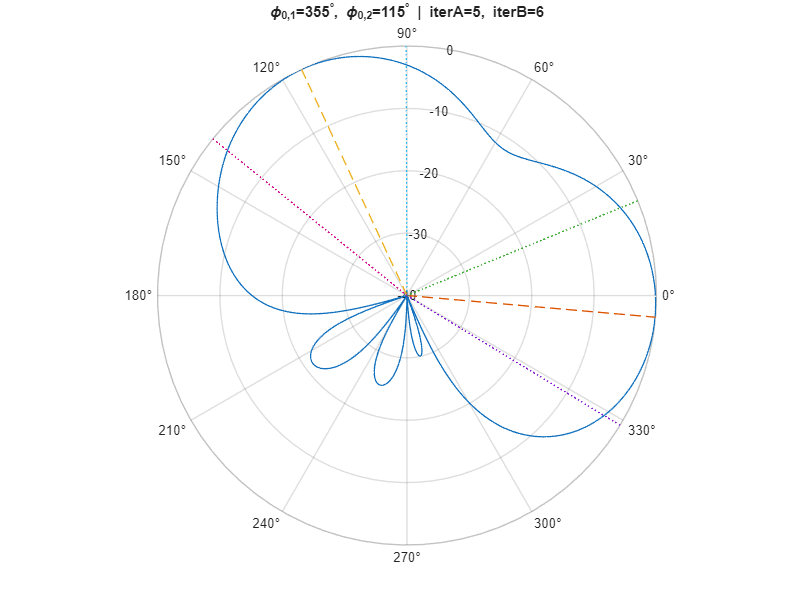

Video frame  10/ 72
Video frame  20/ 72
Video frame  30/ 72
Video frame  40/ 72
Video frame  50/ 72
Video frame  60/ 72
Video frame  70/ 72
Video frame  72/ 72



%% ================================================================
%% BLOCK 2 — LOAD saved steps + BUILD VIDEO (POLAR, dB floor at -40)
%% ================================================================
% Set outdir to the folder created by Block 1.
% Example:
%   outdir = "C:\Users\you\Documents\MATLAB\two_beam_sweep_2026-02-11_203012";

cfg = load(fullfile(outdir,'config.mat'));
phi_mesh      = cfg.phi_mesh;        % theta in radians
phi1_deg_list = cfg.phi1_deg_list;

% ---- dB settings ----
db_floor = -40;                      % origin corresponds to -40 dB
rmax     = -db_floor;                % 40

% ---- Video setup ----
vidfile = fullfile(outdir, 'two_beam_sweep_polar_db.mp4');
v = VideoWriter(vidfile, 'MPEG-4');
v.FrameRate = 20;
open(v);

fig = figure('Color','w');
set(fig,'Position',[100 100 900 700]);

numK = numel(phi1_deg_list);

for k = 1:numK
    phi0_1_deg = phi1_deg_list(k);
    stepfile = fullfile(outdir, sprintf('step_%04d_phi1_%03d.mat', k, phi0_1_deg));
    S = load(stepfile);

    mag = abs(S.F_total);
    mag_max = max(mag);
    if mag_max == 0, mag_max = 1; end

    % Relative dB (peak = 0 dB), floored at db_floor
    mag_db = 20*log10(mag / mag_max);
    mag_db = max(mag_db, db_floor);

    % Map: db_floor -> 0 radius, 0 dB -> rmax
    r = mag_db - db_floor;

    clf(fig);

    % Create polar axes explicitly (more control)
    pax = polaraxes(fig);
    polarplot(pax, phi_mesh, r, 'LineWidth', 1);
    pax.RLim = [0 rmax];
    pax.ThetaLim = [0 360];

    % Radius ticks labeled in dB (so you SEE -40 at the origin)
    rticks = 0:10:rmax;                           % 0..40
    pax.RTick = rticks;
    pax.RTickLabel = string((db_floor:10:0));     % -40..0

    title(pax, sprintf('\\phi_{0,1}=%d^\\circ, \\phi_{0,2}=%d^\\circ | iterA=%d, iterB=%d', ...
        S.phi0_1_deg, S.phi0_2_deg, S.iterA, S.iterB));

    hold(pax, 'on');

    % Mark beam centers as radial lines
    th1 = deg2rad(S.phi0_1_deg);
    th2 = deg2rad(S.phi0_2_deg);
    polarplot(pax, [th1 th1], [0 rmax], '--', 'LineWidth', 1);
    polarplot(pax, [th2 th2], [0 rmax], '--', 'LineWidth', 1);

    % Optional: mark -3 dB beamwidth edges if your bw*_left/right are radians
    polarplot(pax, [S.bw1_left_05  S.bw1_left_05 ], [0 rmax], ':');
    polarplot(pax, [S.bw1_right_05 S.bw1_right_05], [0 rmax], ':');
    polarplot(pax, [S.bw2_left_05  S.bw2_left_05 ], [0 rmax], ':');
    polarplot(pax, [S.bw2_right_05 S.bw2_right_05], [0 rmax], ':');

    hold(pax, 'off');

    drawnow;
    writeVideo(v, getframe(fig));

    if mod(k,10)==0 || k==numK
        fprintf('Video frame %3d/%3d\n', k, numK);
    end
end


close(v);
fprintf('\nDONE polar-dB video.\nMovie:\n  %s\n', vidfile);


DONE polar-dB video.
Movie:
  D:\Research\Dr. Onofreis projects\DS MATLAB CODE\two_beam_crammer_sweep_2026-06-09_164719\two_beam_sweep_polar_db.mp4


## Plot: 2-Beam Function (No-Null Mosier Version)

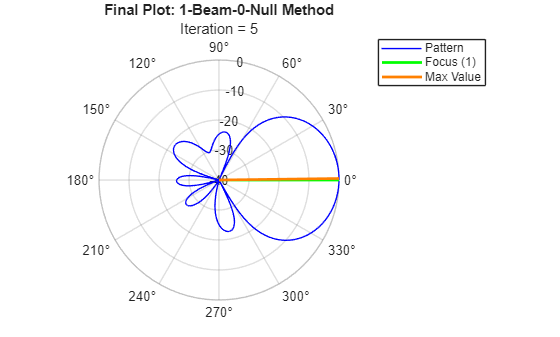

results_2A = struct with fields:
                             final_epoch: 5
                         final_iteration: 5
                              total_time: 0.4064
                                       m: 0
                             focus_angle: 0
                         focus_angle_deg: 0
                                cone_rad: []
                              null_angle: []
                          null_angle_deg: []
                      max_sidelobe_store: [201×1 double]
                      max_side_phi_store: [201×1 double]
                      main_peakLoc_store: [201×1 double]
                      main_peakVal_store: [201×1 double]
                          main_peak_skew: [0 0 0 -0.0126 0 -0.0440]
    directivity_metric_1_beamwidth_store: [201×1 double]
                          final_function: [6.9248 + 0.0000i 6.9266 + 0.0000i 6.9275 + 0.0000i 6.9275 - 0.0000i 6.9265 + 0.0000i 6.9247 + 0.0000i 6.9220 - 0.0000i 6.9183 + 0.0000i 6.9138 + 0.0000i 6.9083 + 0.000

phi_0_1 = deg2rad(0);
phi_0_2 = deg2rad(210);
phi_0_set = [phi_0_1 phi_0_2];
Max_iter = 200;
eps_dB = -20;
null_phi_list_1 = phi_0_2;
null_phi_list_2 = phi_0_1;
N = numel(x);
save_plots = false;

results_2A = perturb_method_v21(Max_iter, eps_dB, x, y, ...
    phi_0_1, ...
    'show_plots', false, ...
    'verbose', false, ...
    'null_phi', [], ...
    'show_final_plot',  true, ...
    'const_null_update', false)

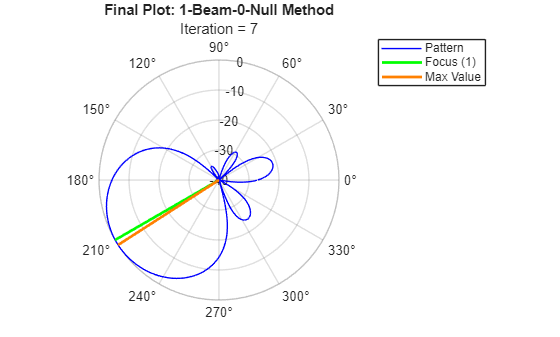

results_2B = struct with fields:
                             final_epoch: 7
                         final_iteration: 7
                              total_time: 0.2324
                                       m: 0
                             focus_angle: 3.6652
                         focus_angle_deg: 210
                                cone_rad: []
                              null_angle: []
                          null_angle_deg: []
                      max_sidelobe_store: [201×1 double]
                      max_side_phi_store: [201×1 double]
                      main_peakLoc_store: [201×1 double]
                      main_peakVal_store: [201×1 double]
                          main_peak_skew: [0.0021 0.0021 0.0398 0.0398 -0.0105 -0.0230 -0.0293 -0.0168]
    directivity_metric_1_beamwidth_store: [201×1 double]
                          final_function: [-0.2807 + 0.0000i -0.2895 + 0.0000i -0.2982 + 0.0000i -0.3069 + 0.0000i -0.3156 + 0.0000i -0.3243 + 0.0000i -0.3329 + 0.0000

results_2B = perturb_method_v21(Max_iter, eps_dB, x, y, ...
    phi_0_2, ...
    'show_plots', false, ...
    'verbose', false, ...
    'null_phi', [], ...
    'show_final_plot',  true, ...
    'const_null_update', false)

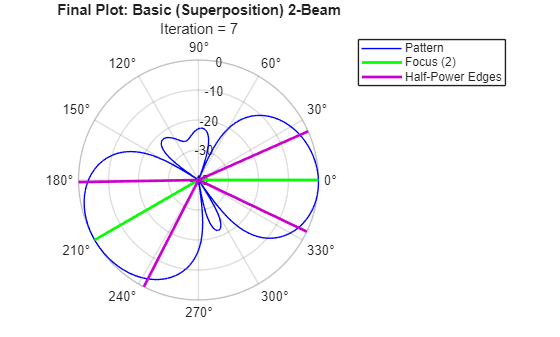

% Add the two plots together to get 2-beam plot
%test_F_total = results_2A.final_function + results_2B.final_function;
scaled_F_A = (N*results_2A.final_function/max(results_2A.final_function));
scaled_F_B = (N*results_2B.final_function/max(results_2B.final_function));
%test_F_total = (N*results_2A.final_function/max(results_2A.final_function)) ...
%+ (N*results_2B.final_function/max(results_2B.final_function));
test_F_total = scaled_F_A + scaled_F_B;

bw1 = directivity_met_v2(phi_mesh, test_F_total, phi_0_1);
bw2 = directivity_met_v2(phi_mesh, test_F_total, phi_0_2);
phi_mesh = linspace(0, 2*pi, 1000);
lab_1 = "Final Plot: Basic (Superposition) 2-Beam";
%lab_1 = "Final Plot: Mosier 2-Beam";
            % View function graph
            plot_pattern_v4(phi_mesh, ...
                abs(test_F_total), ...
                'label',lab_1, ...
                'phi_0', phi_0_set, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05 bw2.right_05],...
                'bw_edges_left', [bw1.left_05 bw2.left_05],...                
                'iter', max(results_2A.final_iteration, results_2B.final_iteration));

## Run a sweep over several Focus Angles for (2-Beam No-Null) version of the Method:

Run a (prototype) sweep over several Focus Angles for (Mosier 2-Beam) version of the Method:

%% ================================================================
%% BLOCK 1 — Sweep + SAVE ONLY (no plots, no video)
%% ================================================================
% Requirements in workspace:
%   x, y
% Functions on path:
%   perturb_method_v17, directivity_met_v2
%
% Output:
%   outdir/
%     config.mat
%     sweep_summary.mat
%     step_0001_phi1_000.mat   (etc)

assert(exist('x','var')==1 && exist('y','var')==1, 'x and y must exist in workspace.');

% IMPORTANT: clear any previous run variables that could conflict
clear all_results cfg S smallA smallB bw1 bw2 results_2A results_2B

% ---- Sweep controls ----
phi_step_deg  = 5;              % try 5, 10, etc. (later can do 1)
phi1_deg_list = 0:phi_step_deg:359;
delta_deg     = 150;            % fixed offset

% ---- Algorithm controls ----
Max_iter = 1000;                % consider lowering if each call is expensive
eps_dB   = -20;

% ---- Pattern mesh ----
phi_mesh = linspace(0, 2*pi, 1000);
phi_mesh = linspace(0, 2*pi, 1000+1);
phi_mesh(end) = [];   % remove 2π duplicate
N = numel(x);

% ---- Output folder (Windows-safe) ----
timestamp = datestr(now,'yyyy-mm-dd_HHMMSS');
outdir = fullfile(pwd, ['two_beam_sweep_' timestamp]);
if ~exist(outdir,'dir'), mkdir(outdir); end

% Save config once (fast)
%save(fullfile(outdir,'config.mat'), ...
%     'phi_step_deg','phi1_deg_list','delta_deg','Max_iter','eps_dB','phi_mesh','N', '-v7');
save(fullfile(outdir,'config.mat'), ...
     'phi_step_deg','phi1_deg_list','delta_deg','Max_iter','eps_dB','cone_rad','fast_peaks','phi_mesh','N', '-v7');

% ---- Preallocate summary struct ROBUSTLY ----
numK = numel(phi1_deg_list);
tmpl = struct( ...
    'k', [], ...
    'phi0_1_deg', [], 'phi0_2_deg', [], ...
    'phi0_1_rad', [], 'phi0_2_rad', [], ...
    'iterA', [], 'iterB', [], ...
    'bw1_left_05', [], 'bw1_right_05', [], ...
    'bw2_left_05', [], 'bw2_right_05', [], ...
    'maxF', [] );
all_results = repmat(tmpl, numK, 1);

fprintf('Saving sweep to:\n  %s\n', outdir);

Saving sweep to:
  D:\Research\Dr. Onofreis projects\DS MATLAB CODE\two_beam_sweep_2026-06-09_164843


tSweep = tic;

for k = 1:numK
    phi0_1_deg = phi1_deg_list(k);
    phi0_2_deg = mod(phi0_1_deg + delta_deg, 360);

    phi_0_1 = deg2rad(phi0_1_deg);
    phi_0_2 = deg2rad(phi0_2_deg);

    % Null lists (your convention)
    null_phi_list_1 = phi_0_2;
    null_phi_list_2 = phi_0_1;

    % ---- Run two optimizations (expensive part) ----
    t0 = tic;
    results_2A = perturb_method_v21(Max_iter, eps_dB, x, y, ...
        phi_0_1, ...
        'show_plots', false, ...
        'verbose', false, ...
        'null_phi', [], ...
        'show_final_plot', false, ...
        'const_null_update', false);

    results_2B = perturb_method_v21(Max_iter, eps_dB, x, y, ...
        phi_0_2, ...
        'show_plots', false, ...
        'verbose', false, ...
        'null_phi', [], ...
        'show_final_plot', false, ...
        'const_null_update', false);
    tOpt = toc(t0);

    % ---- Combine patterns (your normalization) ----
    fa = results_2A.final_function(:).';   % row
    fb = results_2B.final_function(:).';   % row

    maxA = max(fa); if maxA == 0, maxA = 1; end
    maxB = max(fb); if maxB == 0, maxB = 1; end
    
    % N = numel(x);
    F_total = (N * fa / maxA) + (N * fb / maxB);

    % ---- Metrics ----
    bw1 = directivity_met_v2(phi_mesh, F_total, phi_0_1);
    bw2 = directivity_met_v2(phi_mesh, F_total, phi_0_2);

    % ---- Save a SMALL per-step file (FAST) ----
    % Save only what's needed for video/analysis; do NOT save huge result histories.
    iterA = results_2A.final_iteration;
    iterB = results_2B.final_iteration;

    bw1_left_05  = bw1.left_05;
    bw1_right_05 = bw1.right_05;
    bw2_left_05  = bw2.left_05;
    bw2_right_05 = bw2.right_05;

    stepfile = fullfile(outdir, sprintf('step_%04d_phi1_%03d.mat', k, phi0_1_deg));
    save(stepfile, ...
        'k', 'phi0_1_deg','phi0_2_deg','phi_0_1','phi_0_2', ...
        'iterA','iterB', ...
        'F_total', ...
        'bw1_left_05','bw1_right_05','bw2_left_05','bw2_right_05', ...
        '-v7');

    % ---- Store light summary ----
    all_results(k).k           = k;
    all_results(k).phi0_1_deg  = phi0_1_deg;
    all_results(k).phi0_2_deg  = phi0_2_deg;
    all_results(k).phi0_1_rad  = phi_0_1;
    all_results(k).phi0_2_rad  = phi_0_2;
    all_results(k).iterA       = iterA;
    all_results(k).iterB       = iterB;
    all_results(k).bw1_left_05 = bw1_left_05;
    all_results(k).bw1_right_05= bw1_right_05;
    all_results(k).bw2_left_05 = bw2_left_05;
    all_results(k).bw2_right_05= bw2_right_05;
    all_results(k).maxF        = max(abs(F_total));

%    fprintf('k=%3d/%3d | phi1=%3d°, phi2=%3d° | opt=%.2fs\n', ...
%        k, numK, phi0_1_deg, phi0_2_deg, tOpt);
end

save(fullfile(outdir,'sweep_summary.mat'), 'all_results', '-v7');

fprintf('\nDONE sweep.\nTotal time: %.2f min\nFolder:\n  %s\n', toc(tSweep)/60, outdir);


DONE sweep.
Total time: 0.04 min
Folder:
  D:\Research\Dr. Onofreis projects\DS MATLAB CODE\two_beam_sweep_2026-06-09_164843


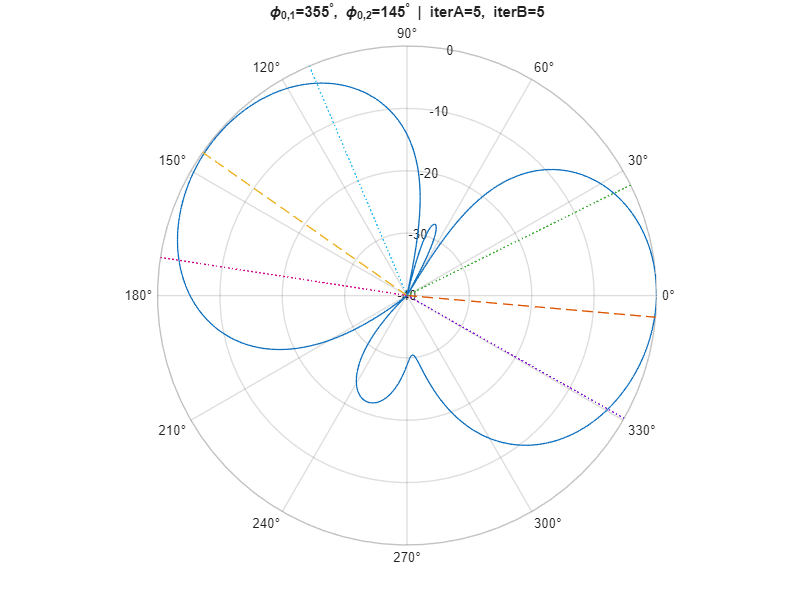

Video frame  10/ 72
Video frame  20/ 72
Video frame  30/ 72
Video frame  40/ 72
Video frame  50/ 72
Video frame  60/ 72
Video frame  70/ 72
Video frame  72/ 72



%% ================================================================
%% BLOCK 2 — LOAD saved steps + BUILD VIDEO (POLAR, dB floor at -40)
%% ================================================================
% Set outdir to the folder created by Block 1.
% Example:
%   outdir = "C:\Users\you\Documents\MATLAB\two_beam_sweep_2026-02-11_203012";

cfg = load(fullfile(outdir,'config.mat'));
phi_mesh      = cfg.phi_mesh;        % theta in radians
phi1_deg_list = cfg.phi1_deg_list;

% ---- dB settings ----
db_floor = -40;                      % origin corresponds to -40 dB
rmax     = -db_floor;                % 40

% ---- Video setup ----
vidfile = fullfile(outdir, 'two_beam_sweep_polar_db.mp4');
v = VideoWriter(vidfile, 'MPEG-4');
v.FrameRate = 20;
open(v);

fig = figure('Color','w');
set(fig,'Position',[100 100 900 700]);

numK = numel(phi1_deg_list);

for k = 1:numK
    phi0_1_deg = phi1_deg_list(k);
    stepfile = fullfile(outdir, sprintf('step_%04d_phi1_%03d.mat', k, phi0_1_deg));
    S = load(stepfile);

    mag = abs(S.F_total);
    mag_max = max(mag);
    if mag_max == 0, mag_max = 1; end

    % Relative dB (peak = 0 dB), floored at db_floor
    mag_db = 20*log10(mag / mag_max);
    mag_db = max(mag_db, db_floor);

    % Map: db_floor -> 0 radius, 0 dB -> rmax
    r = mag_db - db_floor;

    clf(fig);

    % Create polar axes explicitly (more control)
    pax = polaraxes(fig);
    polarplot(pax, phi_mesh, r, 'LineWidth', 1);
    pax.RLim = [0 rmax];
    pax.ThetaLim = [0 360];

    % Radius ticks labeled in dB (so you SEE -40 at the origin)
    rticks = 0:10:rmax;                           % 0..40
    pax.RTick = rticks;
    pax.RTickLabel = string((db_floor:10:0));     % -40..0

    title(pax, sprintf('\\phi_{0,1}=%d^\\circ, \\phi_{0,2}=%d^\\circ | iterA=%d, iterB=%d', ...
        S.phi0_1_deg, S.phi0_2_deg, S.iterA, S.iterB));

    hold(pax, 'on');

    % Mark beam centers as radial lines
    th1 = deg2rad(S.phi0_1_deg);
    th2 = deg2rad(S.phi0_2_deg);
    polarplot(pax, [th1 th1], [0 rmax], '--', 'LineWidth', 1);
    polarplot(pax, [th2 th2], [0 rmax], '--', 'LineWidth', 1);

    % Optional: mark -3 dB beamwidth edges if your bw*_left/right are radians
    polarplot(pax, [S.bw1_left_05  S.bw1_left_05 ], [0 rmax], ':');
    polarplot(pax, [S.bw1_right_05 S.bw1_right_05], [0 rmax], ':');
    polarplot(pax, [S.bw2_left_05  S.bw2_left_05 ], [0 rmax], ':');
    polarplot(pax, [S.bw2_right_05 S.bw2_right_05], [0 rmax], ':');

    hold(pax, 'off');

    drawnow;
    writeVideo(v, getframe(fig));

    if mod(k,10)==0 || k==numK
        fprintf('Video frame %3d/%3d\n', k, numK);
    end
end


close(v);
fprintf('\nDONE polar-dB video.\nMovie:\n  %s\n', vidfile);


DONE polar-dB video.
Movie:
  D:\Research\Dr. Onofreis projects\DS MATLAB CODE\two_beam_sweep_2026-06-09_164843\two_beam_sweep_polar_db.mp4


## Compare Double-Cross vs. Regular N-gon Geometry

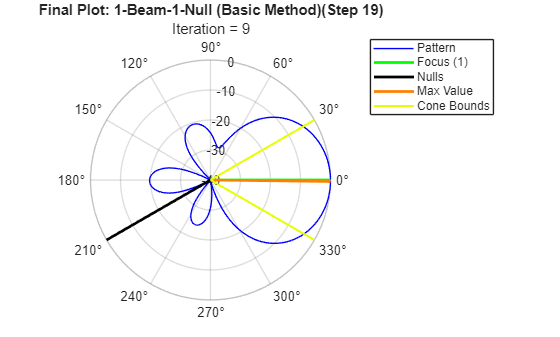

%% Shared Base Variables
Max_iter = 200; %The algithm goes to step maxiter
eps_dB = -20;
phi_0_1 = deg2rad(0);
phi_0_2 = deg2rad(210);
phi_0_set = [phi_0_1 phi_0_2];
%phi_0 = deg2rad(0);
%null_phi_list = deg2rad([120]);
null_phi_list_1 = phi_0_2;
null_phi_list_2 = phi_0_1;
cone_rad = deg2rad(30);
N = 9;
%N = numel(x);
phi = linspace(0, 2*pi, 1000+1);   % MUST match algorithm
phi(end) = [];   % remove 2π duplicate
nPhi = numel(phi);



%% Double Cross Version
% Initialize Eric's 'better' 9-element version (specifically for 120 degrees)
d1 = 0.049553426571036;
d2 = 0.049015017974167;
[x,y] = d1d2Convert(d1,d2,N);

results_1A = perturb_method_v22(Max_iter, eps_dB, x, y, phi_0_1, ...
    'null_phi', null_phi_list_1, ...
    'show_plot_raw', false, ...
    'show_plot_init', false, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true);

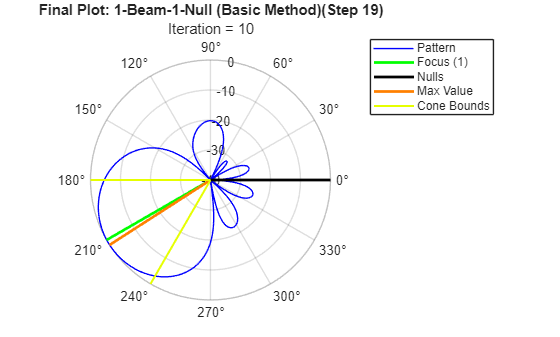


results_1B = perturb_method_v22(Max_iter, eps_dB, x, y, phi_0_2, ...
    'null_phi', null_phi_list_2, ...
    'show_plot_raw', false, ...
    'show_plot_init', false, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true);

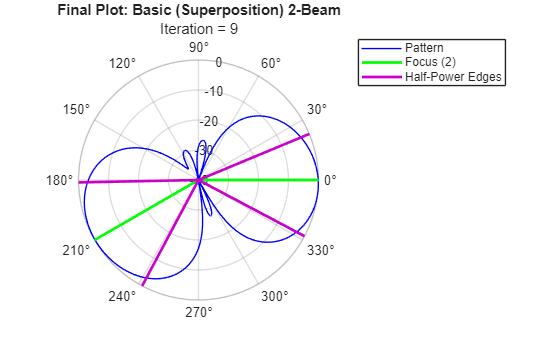

% Add the two plots together to get 2-beam plot
%test_F_total = results_2A.final_function + results_2B.final_function;
%results_1C_F_total = (N*results_1A.final_function/max(results_1A.final_function)) ...
%+ (N*results_1B.final_function/max(results_1B.final_function));
%results_1C_A_total = results_1A.A_eff + results_1B.A_eff;

results_1C_A_total = (N*results_1A.A_eff ./ max(abs(results_1A.final_function))) ...
+ (N*results_1B.A_eff ./ max(abs(results_1B.final_function)));

results_1C_F_total = F2d_v2(phi_mesh, results_1C_A_total, x, y, [], k0);

phi_mesh = phi;
bw1 = directivity_met_v2(phi_mesh, results_1C_F_total, phi_0_1);
bw2 = directivity_met_v2(phi_mesh, results_1C_F_total, phi_0_2);
%phi_mesh = linspace(0, 2*pi, 1000);
lab_1 = "Final Plot: Basic (Superposition) 2-Beam";
%lab_1 = "Final Plot: Mosier 2-Beam";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                abs(results_1C_F_total), ...
                'label',lab_1, ...
                'phi_0', phi_0_set, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05 bw2.right_05],...
                'bw_edges_left', [bw1.left_05 bw2.left_05],...                
                'iter', max(results_1A.final_iteration, results_1B.final_iteration));

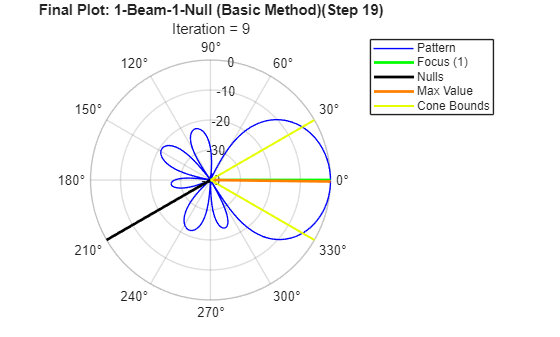

%{
% Record Final value at focus angle
F_at_phi_0_1 = interp1(phi, results_1C_F_total, phi_0_1, 'linear', 'extrap');
F_at_phi_0_2 = interp1(phi, results_1C_F_total, phi_0_2, 'linear', 'extrap');
% Record Gains
G_1 = gain_calc(results_1C_F_total, phi, phi_0_1);
G_2 = gain_calc(results_1C_F_total, phi, phi_0_2);
%}

%% Regular N-gon Version
% Initialize "All on one ring" version of the 9-element "double cross" coordinates
% This is equivalent to an regular octogon with radius 0.05 starting at (0.05,0).
%z = zeros(1,N);
d1 = 0.04880;
d2 = 0.04880;
[x,y] = d1d2Convert(d1,d2,9); %Change to 5,9,13 apropriatly


results_2A = perturb_method_v22(Max_iter, eps_dB, x, y, phi_0_1, ...
    'null_phi', null_phi_list_1, ...
    'show_plot_raw', false, ...
    'show_plot_init', false, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true);

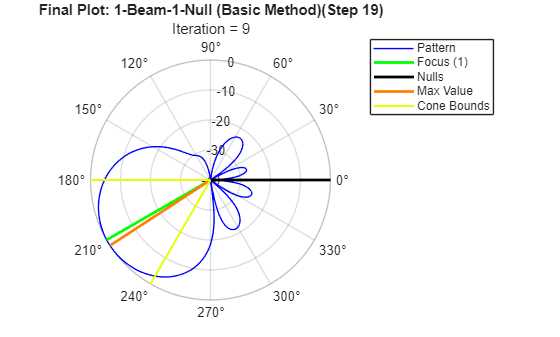


results_2B = perturb_method_v22(Max_iter, eps_dB, x, y, phi_0_2, ...
    'null_phi', null_phi_list_2, ...
    'show_plot_raw', false, ...
    'show_plot_init', false, ...
    'show_plots_st7', false, ...
    'show_plots_st12', false, ...
    'show_plots_st16', false, ...
    'show_final_plot',  true, ...
    'cone_rad', cone_rad, ...
    'A_init', [], ...
    'return_funcs', true);

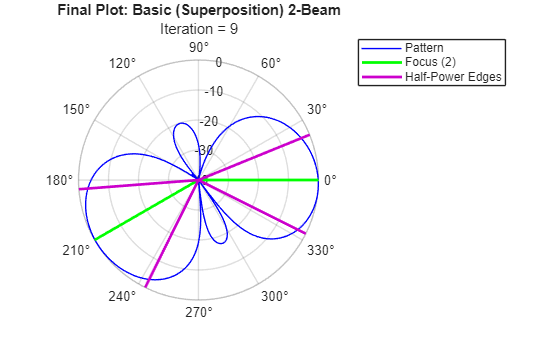

% Add the two plots together to get 2-beam plot
%test_F_total = results_2A.final_function + results_2B.final_function;
%results_2C_F_total = (N*results_2A.final_function/max(results_2A.final_function)) ...
%+ (N*results_2B.final_function/max(results_2B.final_function));
%results_2C_A_total = results_2A.A_eff + results_2B.A_eff;
%results_2C_F_total = F2d_v2(phi_mesh, results_2C_A_total, x, y, [], k0);

results_2C_A_total = (N*results_2A.A_eff ./ max(abs(results_2A.final_function))) ...
+ (N*results_2B.A_eff ./ max(abs(results_2B.final_function)));

results_2C_F_total = F2d_v2(phi_mesh, results_2C_A_total, x, y, [], k0);

phi_mesh = phi;
bw1 = directivity_met_v2(phi_mesh, results_2C_F_total, phi_0_1);
bw2 = directivity_met_v2(phi_mesh, results_2C_F_total, phi_0_2);
%phi_mesh = linspace(0, 2*pi, 1000);
lab_1 = "Final Plot: Basic (Superposition) 2-Beam";
%lab_1 = "Final Plot: Mosier 2-Beam";
            % View function graph
            plot_pattern_v5(phi_mesh, ...
                abs(results_2C_F_total), ...
                'label',lab_1, ...
                'phi_0', phi_0_set, ...
                'show_plots', true, ...
                'cone_rad', [], ...
                'bw_edges_right', [bw1.right_05 bw2.right_05],...
                'bw_edges_left', [bw1.left_05 bw2.left_05],...                
                'iter', max(results_1A.final_iteration, results_1B.final_iteration));



%% Combine run data
runs = {results_1C_F_total, results_2C_F_total};
labels = {"Double Cross", "Regular N-gon"};
Nruns = numel(runs);

%% Extract and Trim Data from Each Run
bw_1_all = cell(Nruns,1);
bw_2_all = cell(Nruns,1);
F_focus_all = cell(Nruns,1);
G_all = cell(Nruns,1);

for r = 1:Nruns

    res = runs{r}; % set target results

    phi_mesh = phi;
    bw1_store = directivity_met_v2(phi_mesh, res, phi_0_1);
    bw2_store = directivity_met_v2(phi_mesh, res, phi_0_2);
    %bw_store = res.directivity_metric_1_beamwidth_store;
    % Record Final value at focus angle
    F_at_phi_0_1 = interp1(phi, res, phi_0_1, 'linear', 'extrap');
    F_at_phi_0_2 = interp1(phi, res, phi_0_2, 'linear', 'extrap');
    %F_focus_store = res.focus_value_store;
    % Record Gains
    G_1 = gain_calc(res, phi, phi_0_1);
    G_2 = gain_calc(res, phi, phi_0_2);
    %G = function gain_calc(F_total, phi_mesh, phi0)
    %G_store = gain_calc(res.F_store, phi, phi_0);

    % Determine valid entries
    valid_mask = ~(isnan(F_at_phi_0_1) | isinf(F_at_phi_0_1));
    last_valid = find(valid_mask, 1, 'last');

    if isempty(last_valid)
        error('Run %d has no valid entries.', r);
    end

    % Trim
    bw1_all{r} = bw1_store(1:last_valid);
    bw2_all{r} = bw2_store(1:last_valid);
    F_focus_1_all{r} = F_at_phi_0_1(1:last_valid);
    F_focus_2_all{r} = F_at_phi_0_2(1:last_valid);
    G_1_all{r} = G_1(1:last_valid);
    G_2_all{r} = G_2(1:last_valid);

end

## Compare Final Gains, Focus Values, Beamwidths

G_1_final = zeros(Nruns,1);
G_2_final = zeros(Nruns,1);
F_focus_1_final = zeros(Nruns,1);
F_focus_2_final = zeros(Nruns,1);

for r = 1:Nruns
    % Gain at both directions
    G_1_final(r) = gain_calc(runs{r}, phi, phi_0_1);
    G_2_final(r) = gain_calc(runs{r}, phi, phi_0_2);
    %GN_Final(r) = gain_calc(runs{r}, phi, null_phi_list);
    
    % Final focus values (last entry)
    F_focus_1_final(r) = abs(F_focus_1_all{r}(end));
    F_focus_2_final(r) = abs(F_focus_2_all{r}(end));
end

% Convert for MATLAB bar(): (rows = categories, columns = groups)
G_mat = [G_1_final, G_2_final];
F_mat = [F_focus_1_final, F_focus_2_final];

figure;
%bar(G_1_final);
%bar(G_2_final);
b = bar(G_mat);   % grouped bars

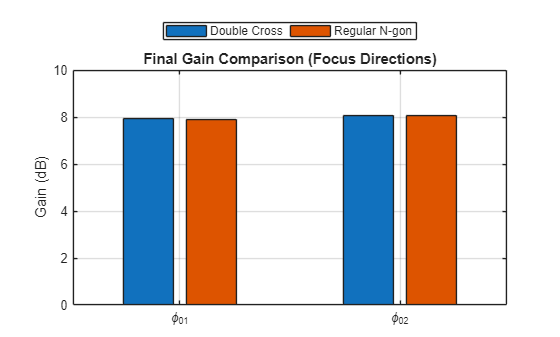


% Set colors (Double Cross vs N-gon)
colors = lines(Nruns);
for r = 1:Nruns
    b(r).FaceColor = colors(r,:);
end

%set(gca, 'XTickLabel', labels);
set(gca, 'XTickLabel', {'\phi_0_1','\phi_0_2'})
ylabel('Gain (dB)');
title('Final Gain Comparison (Focus Directions)');
%legend({'\phi_0_1','\phi_0_2'}, 'Location','best');
%legend({'\phi_0_1','\phi_0_2'}, 'Location','eastoutside');
legend(labels, 'Location','northoutside','Orientation','horizontal');
grid on;

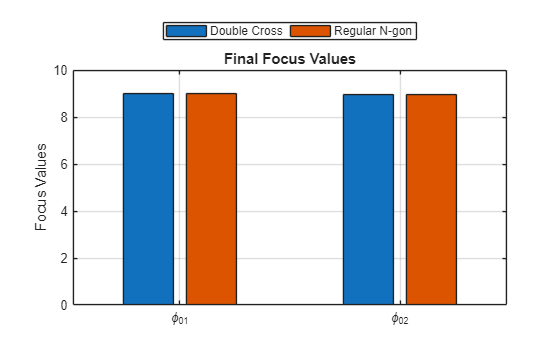

figure;
%bar(F_focus_1_final);
%bar(F_focus_2_final);
b = bar(F_mat.');   % grouped bars

% Set colors (Double Cross vs N-gon)
colors = lines(Nruns);
for r = 1:Nruns
    b(r).FaceColor = colors(r,:);
end

%set(gca, 'XTickLabel', labels);
set(gca, 'XTickLabel', {'\phi_0_1','\phi_0_2'})
ylabel('Focus Values');
title('Final Focus Values');
%legend({'\phi_0_1','\phi_0_2'}, 'Location','best');
legend(labels, 'Location','northoutside','Orientation','horizontal');
grid on;

## CPU Time Test

%N = 1e5;                    % adjust until total time is > 1 second
N = 1e2;                    % adjust until total time is > 1 second
t0 = cputime;
for k = 1:N
    %myFunction(x, y);
    Max_iter = 200; %The algithm goes to step maxiter
    eps_dB = -20;
    %phi_0 = deg2rad(225);
    %null_phi_list = deg2rad([]);
    %cone_rad = deg2rad(30);
    cone_rad = [];
    phi_0_1 = deg2rad(120);
    phi_0_2 = deg2rad(0);
    %phi_0_set = [phi_0_1 phi_0_2];
    %null_phi_list_1 = phi_0_2;
    %null_phi_list_2 = phi_0_1;
    results_1 = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, ...
    phi_0_1, ...
    'null_phi',        phi_0_2, ...
    'cone_rad',        cone_rad, ...
    'show_plots',      false, ...
    'show_final_plot', false, ...
    'verbose',         false, ...
    'return_funcs',    false);
end
cpu_per_call_ms = (cputime - t0) / N * 1000;
fprintf('CPU time per call: %.4f ms\n', cpu_per_call_ms);

## CPU Time Test (superposition)

%N = 1e5;                    % adjust until total time is > 1 second
N = 1e2;                    % adjust until total time is > 1 second
t0 = cputime;
for k = 1:N
    %myFunction(x, y);
    Max_iter = 200; %The algithm goes to step maxiter
    eps_dB = -20;
    %phi_0 = deg2rad(225);
    %null_phi_list = deg2rad([]);
    %cone_rad = deg2rad(30);
    cone_rad = [];
    phi_0_2 = deg2rad(225);
    phi_0_1 = deg2rad(225+120);
    %phi_0_set = [phi_0_1 phi_0_2];
    null_phi_list_1 = phi_0_2;
    null_phi_list_2 = phi_0_1;
    results_1 = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, ...
    phi_0_1, ...
    'null_phi',        null_phi_list_1, ...
    'cone_rad',        cone_rad, ...
    'fast_peaks',      fast_peaks, ...
    'show_plots',      false, ...
    'show_final_plot', false, ...
    'verbose',         false, ...
    'return_funcs',    false);
    results_2 = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, ...
    phi_0_2, ...
    'null_phi',        null_phi_list_2, ...
    'cone_rad',        cone_rad, ...
    'fast_peaks',      fast_peaks, ...
    'show_plots',      false, ...
    'show_final_plot', false, ...
    'verbose',         false, ...
    'return_funcs',    false);
end
cpu_per_call_ms = (cputime - t0) / N * 1000;
fprintf('CPU time per call: %.4f ms\n', cpu_per_call_ms);

CPU time per call: 7302.0312 ms


## Get the Focus Gain, Null Gain, Angle Distance between Max and Focus Direction, Max Sidelobe Level

%% Sweep: 1-Beam method at 4 focus directions — gain, skew, max sidelobe
%phi_deg_list = [0 31 45 135 225];
phi_deg_list = [0 45 135 225];
Max_iter     = 200;
eps_dB       = -20;
d1           = 0.04880;
d2           = 0.04880;
N            = 9;
[x, y]       = d1d2Convert(d1, d2, N);

fprintf('\n');
fprintf('  phi_0    G2D(focus)    G3D(focus)    G2D(null)    main-beam skew   max sidelobe\n');

  phi_0    G2D(focus)    G3D(focus)    G2D(null)    main-beam skew   max sidelobe


fprintf('  -----    ----------    ----------    ---------    --------------   ------------\n');

  -----    ----------    ----------    ---------    --------------   ------------



for k = 1:numel(phi_deg_list)
    phi_0 = deg2rad(phi_deg_list(k));
    phi_N = deg2rad(phi_deg_list(k)+90);

    r = Crammer_Simultaneous_Constraints_v2(Max_iter, eps_dB, x, y, phi_0, ...
        'null_phi',        phi_N, ...
        'show_plots',      false, ...
        'show_final_plot', false, ...
        'verbose',         false);

    if isempty(r.null_gain2D)
        null_str = '    N/A   ';
    else
        null_str = sprintf('%9.3f', r.null_gain2D);
    end

    fprintf('  %3d°   %9.3f dB  %9.3f dB   %s    %7.3f°       %7.3f dB\n', ...
        phi_deg_list(k), ...
        r.final_gain2D, ...
        r.final_gain3D, ...
        null_str, ...
        r.main_beam_skew_final_deg, ...
        r.final_max_sidelobe_dB);
end

    0°      11.463 dB      9.840 dB        -Inf      1.080°       -22.808 dB
   45°      11.434 dB      9.817 dB    -342.385      1.080°       -22.808 dB
  135°      11.432 dB      9.814 dB    -320.804      1.080°       -22.808 dB
  225°      11.432 dB      9.814 dB    -308.750      1.080°       -22.808 dB


fprintf('\n');

## Sweep: 2-Beam Superposition Method at 4 primary focus directions — gains, skews, max sidelobe: 1-B-1-N Version with Simultaneous Constraints

%% 2-Beam Superposition (1-B-1-N) — gains, skews, max sidelobe
phi_deg_list_1   = [0 45 135 225];
secondary_offset = 120;
Max_iter         = 200;
eps_dB           = -20;
d1 = 0.04880;
d2 = 0.04880;
N  = 9;
[x, y] = d1d2Convert(d1, d2, N);

fprintf('\n');
fprintf('  phi_1   phi_2    G2D_1        G2D_2        G3D_1        G3D_2       skew_1    skew_2     BW_1      BW_2    max sidelobe\n');

  phi_1   phi_2    G2D_1        G2D_2        G3D_1        G3D_2       skew_1    skew_2    max sidelobe


fprintf('  -----   -----    -----        -----        -----        -----       ------    ------     ----      ----    ------------\n');

  -----   -----    -----        -----        -----        -----       ------    ------    ------------



for k = 1:numel(phi_deg_list_1)
    phi_0_1_deg = phi_deg_list_1(k);
    phi_0_2_deg = mod(phi_0_1_deg + secondary_offset, 360);
    phi_0_1 = deg2rad(phi_0_1_deg);
    phi_0_2 = deg2rad(phi_0_2_deg);

    % --- variant-specific: 1-B-1-N solves ---
    resA = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, phi_0_1, ...
        'null_phi', phi_0_2, 'cone_rad', deg2rad(30), 'fast_peaks', true, ...
        'show_plots', false, 'show_final_plot', false, 'verbose', false);
    resB = Crammer_Simultaneous_Constraints(Max_iter, eps_dB, x, y, phi_0_2, ...
        'null_phi', phi_0_1, 'cone_rad', deg2rad(30), 'fast_peaks', true, ...
        'show_plots', false, 'show_final_plot', false, 'verbose', false);
    

    % --- variant-agnostic: combine + measure ---
    m = combined_2beam_metrics(resA, resB, phi_0_1, phi_0_2, x, y);

    fprintf(['  %3d°    %3d°   %9.3f dB %9.3f dB %9.3f dB %9.3f dB' ...
             '   %7.3f°  %7.3f°  %7.3f°  %7.3f°    %9.3f dB\n'], ...
        phi_0_1_deg, phi_0_2_deg, ...
        m.final_gain2D_1, m.final_gain2D_2, ...
        m.final_gain3D_1, m.final_gain3D_2, ...
        m.main_beam_skew_final_1_deg, m.main_beam_skew_final_2_deg, ...
        m.beamwidth_1_deg, m.beamwidth_2_deg, ...
        m.final_max_sidelobe_dB);

    0°    120°       8.134 dB     8.125 dB     7.433 dB     7.423 dB     1.440°    1.560°      -15.830 dB
   45°    165°       8.122 dB     8.112 dB     7.421 dB     7.412 dB     1.440°    1.560°      -15.830 dB
  135°    255°       8.120 dB     8.111 dB     7.422 dB     7.412 dB     1.440°    1.560°      -15.830 dB
  225°    345°       8.131 dB     8.121 dB     7.429 dB     7.420 dB     1.440°    1.560°      -15.830 dB


end
fprintf('\n');